# Explore the dynamics of a TRIPLE compound **Pendulum**

In this example we're going to derive and then implement the equations of motion for a TRIPLE compound  pendulum. Specifically we're going to:

- Derive the equations of motion using's Lagrange's method

The system that we're going to explore is shown below.  At each joint we have:

- $\tau_m$   :     Actuation torques (eg: by electric motors)

- $b.\dot{\theta}$  :    Viscous damping torques

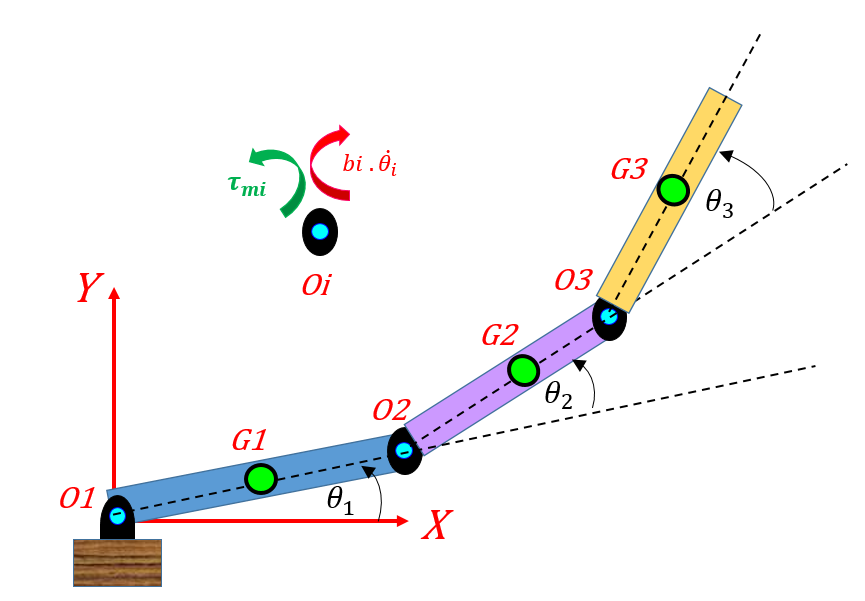 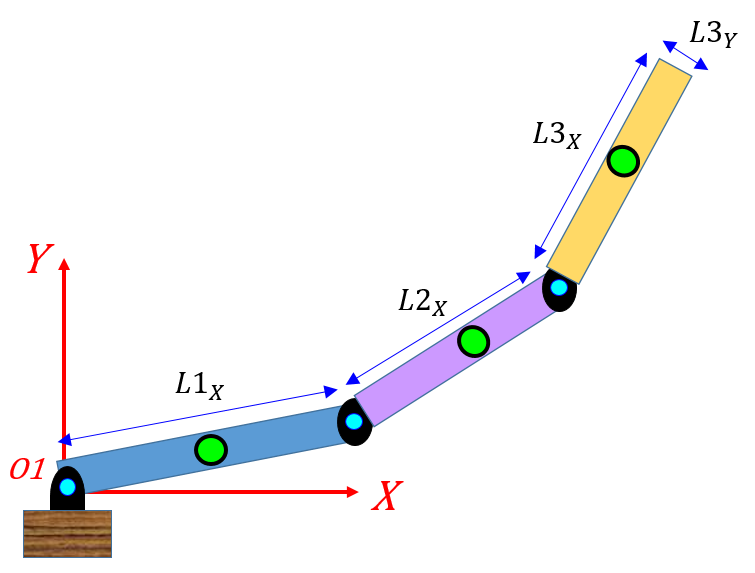

`Bradley Horton : 01-Aug-2016, bradley.horton@mathworks.com.au`           

# **STAGE 1:** symbolic derivation of system equations

## Euler-Lagrange equations of motion

                           $\frac{d}{dt}\frac{\partial L}{\partial \dot{q}_k} - \frac{\partial L}{\partial q_k} = Q_k $     for     $k=1,2, \dots, n$

where  *n* is the DOF of the system, {$q_1, q_2, \dots, q_n$} is a set of generalized coordinates, {$Q_1, Q_2, \dots, Q_n$} is the set of generalized forces associated with those coordinates, and the Lagrangian:  ***L***** =  *****T***  ***-***  ***V****,* is defined as the difference between the kinetic and potential energy of the  *n-* DOF system.  The Generalised forces can also be defined in terns of the non conservative forces and torques acting on the multibody system.  The formula for the generalised forces acting on the system is:


$$Q_k = 
\sum_{i=1}^{Nf_{nc}}
\pmatrix{
\vec{F_i} \thinspace . \thinspace \frac{\partial \vec{v \thinspace _i}}{\partial \dot{q \thinspace}_k}
}  \enspace + \enspace
\sum_{j=1}^{N\tau_{nc}}
\pmatrix{
\vec {\tau_j} \thinspace . \thinspace \frac{\partial \vec{\omega \thinspace _j}}{\partial \dot{q \thinspace}_k}
}
$$


where:

- $Q_k$     :    is the generalised force associated with the $k^{th}$ generalised co-ordinate $q_k$

- $Nf_{nc}$ :    is the number of active NON conservative forces

- $N\tau_{nc}$:    is the number of active NON conservative TORQUES

- $\vec{v_i}$    :    is the velocity vector of the point associated with the applied force.

- $\vec{\omega_i}$   :    is the angular velocity about the point associated with the applied torque. 

**Note** : 

- For our system, we will choose  *q = {*$\theta_1 \thinspace, \theta_2 \thinspace, \theta_3$*}* 

- This is a 3 degree of freedom system, and as such there are three 2nd order ODEs that can be derived.

## Defining Model parameters and velocities for the two Links:

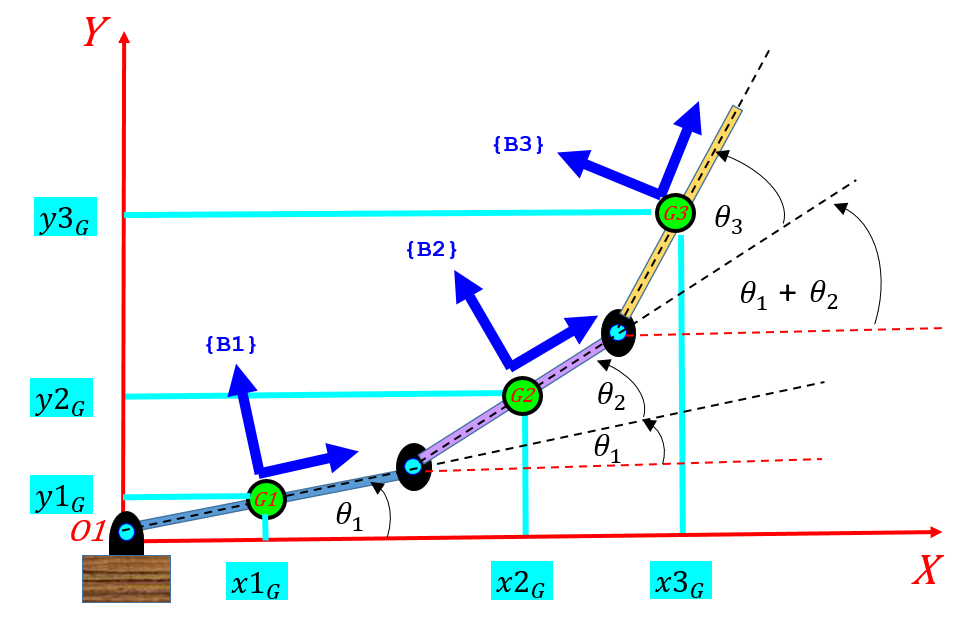     

Here are some model parameters:

syms    m2_s      m1_s       m3_s
syms   I1G_s     I2G_s       I3G_s
syms    b1_s      b2_s       b3_s
syms taum1_s   taum2_s    taum3_s
syms     g_s 

Here are some geometry parameters:

syms L1X_s L2X_s L3X_s 
syms t theta1(t)  TH1_s  
syms   theta2(t)  TH2_s  
syms   theta3(t)  TH3_s  

Here's ${X}_{1G} \enspace , \enspace
{Y}_{1G} 
$

X1_G        = (L1X_s/2)*cos(theta1(t));
Y1_G        = (L1X_s/2)*sin(theta1(t));

Here's ${X}_{2G} \enspace , \enspace
{Y}_{2G} 
$

alpha       = theta1(t) + theta2(t);
X2_G        = L1X_s*cos(theta1(t)) + (L2X_s/2)*cos(alpha);
Y2_G        = L1X_s*sin(theta1(t)) + (L2X_s/2)*sin(alpha);

Here's ${X}_{3G} \enspace , \enspace
{Y}_{3G} 
$

beta        = theta1(t) + theta2(t) + theta3(t);
X3_G        = L1X_s*cos(theta1(t)) + L2X_s*cos(alpha) + (L3X_s/2)*cos(beta);
Y3_G        = L1X_s*sin(theta1(t)) + L2X_s*sin(alpha) + (L3X_s/2)*sin(beta);

Here's $\dot{X}_{1G} \enspace , \enspace
\ddot{X}_{1G} \enspace , \enspace
\dot{Y}_{1G} \enspace , \enspace
\ddot{Y}_{1G} $

X1_G_d      = diff(X1_G, t); 
X1_G_dd     = diff(X1_G, t, 2); 

Y1_G_d      = diff(Y1_G, t); 
Y1_G_dd     = diff(Y1_G, t, 2); 

Here's $\dot{X}_{2G} \enspace , \enspace
\ddot{X}_{2G} \enspace , \enspace
\dot{Y}_{2G} \enspace , \enspace
\ddot{Y}_{2G} $

X2_G_d      = diff(X2_G, t); 
X2_G_dd     = diff(X2_G, t, 2); 

Y2_G_d      = diff(Y2_G, t); 
Y2_G_dd     = diff(Y2_G, t, 2);

Here's $\dot{X}_{3G} \enspace , \enspace
\ddot{X}_{3G} \enspace , \enspace
\dot{Y}_{3G} \enspace , \enspace
\ddot{Y}_{3G} $

X3_G_d      = diff(X3_G, t); 
X3_G_dd     = diff(X3_G, t, 2); 

Y3_G_d      = diff(Y3_G, t); 
Y3_G_dd     = diff(Y3_G, t, 2);

## Define the system KINETIC energy:

Our TRANSLATIONAL kinetic energy is:

KE_trans = 0.5*m1_s*( X1_G_d^2  + Y1_G_d^2) + ...
           0.5*m2_s*( X2_G_d^2  + Y2_G_d^2) + ...
           0.5*m3_s*( X3_G_d^2  + Y3_G_d^2);

Our ROTATIONAL kinetic energy is:

theta1_d   = diff(theta1, t);
theta2_d   = diff(theta2, t);
theta3_d   = diff(theta3, t);

KE_rot   = 0.5*I1G_s*( (theta1_d                      )^2 )  + ...
           0.5*I2G_s*( (theta1_d + theta2_d           )^2 )  + ...
           0.5*I3G_s*( (theta1_d + theta2_d + theta3_d)^2 );

So our total kinetic energy is:

KE = KE_trans + KE_rot;      

## Define the system POTENTIAL energy:

Our Potential energy is:

PE = g_s*(m1_s*Y1_G  + m2_s*Y2_G  + m3_s*Y3_G);

## Define the system Lagrangian:

L_ORIGINAL = KE - PE;

Note the symbolic variables that are inside the Lagrangian:

symvar(  L_ORIGINAL  )

$$ans = \left(\begin{array}{ccccccccccc} {\mathrm{I1G}}_{s} & {\mathrm{I2G}}_{s} & {\mathrm{I3G}}_{s} & {\mathrm{L1X}}_{s} & {\mathrm{L2X}}_{s} & {\mathrm{L3X}}_{s} & g_{s} & m_{1,s} & m_{2,s} & m_{3,s} & t \end{array}\right)$$

Now all we need to do is a series of derivative calculations according to Lagrange's equation:

 
$$\frac{d}{dt}\frac{\partial L}{\partial \dot{q}_k} - \frac{\partial L}{\partial q_k} = Q_k $$
 

## Apply Lagrange's equation:

So let's now apply Lagrange's equation:

-  $\frac{d}{dt}\frac{\partial L}{\partial \dot{q}_k} - \frac{\partial L}{\partial q_k} = Q_k $     for     $k=1,2, \dots, n$

First we'll define our generalised co-ordinates.  I'm going to use 2 sets of these generalised co-ordinates:

- the **ACTUAL** set of symbols are our "proper" set of symbols

- the **HOLDER** set are for easier expression manipulation

actual_list_SYM_pos = formula( [     theta1,      theta2,      theta3  ]  );
holder_list_SYM_pos = [                 TH1_s,       TH2_s        TH3_s];

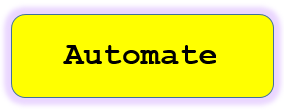

OK:  let's create a Lagrangian object using the class <`bh_lagr4manips_CLS`>

lag_OBJ = bh_lagr4manips_CLS( KE, PE, actual_list_SYM_pos, holder_list_SYM_pos);

And let's compute the system's equations of motion:

lag_OBJ = lag_OBJ.calc_eom()

lag_OBJ =   bh_lagr4manips_CLS with properties:

                   T_KE: [1×1 sym]
                   V_PE: [1×1 sym]
                      L: [1×1 sym]
                Qk_list: [3×1 sym]
                    EOM: [1×3 bh_eom_CLS]
                  N_dof: 3
    actual_list_SYM_pos: [3×1 sym]
    actual_list_SYM_vel: [3×1 sym]
    actual_list_SYM_acc: [3×1 sym]
    holder_list_SYM_pos: [3×1 sym]
    holder_list_SYM_vel: [3×1 sym]
    holder_list_SYM_acc: [3×1 sym]


So what do the equations of motion actually look like ?

lag_OBJ.show_eom()


#######################################################
### q = theta1(t)
### 
### LHS of EOM is: 
### 
        I1G_s*diff(theta1(t), t, t) + I2G_s*diff(theta1(t), t, t) + I2G_s*diff(theta2(t), t, t) + I3G_s*diff(theta1(t), t, t) + I3G_s*diff(theta2(t), t, t) + I3G_s*diff(theta3(t), t, t) + (L1X_s^2*m1_s*diff(theta1(t), t, t))/4 + L1X_s^2*m2_s*diff(theta1(t), t, t) + L1X_s^2*m3_s*diff(theta1(t), t, t) + (L2X_s^2*m2_s*diff(theta1(t), t, t))/4 + (L2X_s^2*m2_s*diff(theta2(t), t, t))/4 + L2X_s^2*m3_s*diff(theta1(t), t, t) + L2X_s^2*m3_s*diff(theta2(t), t, t) + (L3X_s^2*m3_s*diff(theta1(t), t, t))/4 + (L3X_s^2*m3_s*diff(theta2(t), t, t))/4 + (L3X_s^2*m3_s*diff(theta3(t), t, t))/4 + (L2X_s*g_s*m2_s*cos(theta1(t) + theta2(t)))/2 + L2X_s*g_s*m3_s*cos(theta1(t) + theta2(t)) + (L1X_s*g_s*m1_s*cos(theta1(t)))/2 + L1X_s*g_s*m2_s*cos(theta1(t)) + L1X_s*g_s*m3_s*cos(theta1(t)) + (L3X_s*g_s*m3_s*cos(theta1(t) + theta2(t) + theta3(t)))/2 - (L1X_s*L3X_s*m3_s*sin(theta2(t) + theta3(t))*diff(theta2(t), 

You can also(if you want to) look at these equations in a text file called `<bh_tmp_EOM_file_WILL_BE_DELETED.txt>`:

lag_OBJ.show_eom_in_txt_file()

We can retrieve the $1^{st}$equation of motion:

lag_OBJ.get_eom( 1, 'actual', 'LHS')

lag_OBJ.get_eom( 1, 'actual', 'RHS')

$$ans = Q_{1,s}$$

And we can retrieve the $2^{nd}$equation of motion:

lag_OBJ.get_eom( 2, 'actual', 'LHS')

lag_OBJ.get_eom( 2, 'actual', 'RHS')

$$ans = Q_{2,s}$$

And we can retrieve the $3^{rd}$equation of motion:

lag_OBJ.get_eom( 3, 'actual', 'LHS')

$$ans = \begin{array}{l} {\mathrm{I3G}}_{s}\,\sigma_{1}+{\mathrm{I3G}}_{s}\,\sigma_{2}+{\mathrm{I3G}}_{s}\,\sigma_{5}+\frac{{{\mathrm{L3X}}_{s}}^{2}\,m_{3,s}\,\sigma_{1}}{4}+\frac{{{\mathrm{L3X}}_{s}}^{2}\,m_{3,s}\,\sigma_{2}}{4}+\frac{{{\mathrm{L3X}}_{s}}^{2}\,m_{3,s}\,\sigma_{5}}{4}+\frac{{\mathrm{L3X}}_{s}\,g_{s}\,m_{3,s}\,\cos\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)+\theta_{3}\left(t\right)\right)}{2}+\frac{{\mathrm{L1X}}_{s}\,{\mathrm{L3X}}_{s}\,m_{3,s}\,\sin\left(\sigma_{4}\right)\,\sigma_{3}}{2}+\frac{{\mathrm{L1X}}_{s}\,{\mathrm{L3X}}_{s}\,m_{3,s}\,\cos\left(\sigma_{4}\right)\,\sigma_{1}}{2}+\frac{{\mathrm{L2X}}_{s}\,{\mathrm{L3X}}_{s}\,m_{3,s}\,\sin\left(\theta_{3}\left(t\right)\right)\,\sigma_{3}}{2}+\frac{{\mathrm{L2X}}_{s}\,{\mathrm{L3X}}_{s}\,m_{3,s}\,\sin\left(\theta_{3}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}}{2}+\frac{{\mathrm{L2X}}_{s}\,{\mathrm{L3X}}_{s}\,m_{3,s}\,\cos\left(\theta_{3}\left(t\right)\right)\,\sigma_{1}}{2}+\frac{{\mathrm{L2X}}_{s}\,{\mathrm{L3X}}_{s}\,m_{3,s}\,\cos\left(\theta_{3}\left(t\right)\right)\,\sigma_{2}}{2}+{\mathrm{L2X}}_{s}\,{\mathrm{L3X}}_{s}\,m_{3,s}\,\sin\left(\theta_{3}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)\\ \sigma_{3}={\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}\\ \sigma_{4}=\theta_{2}\left(t\right)+\theta_{3}\left(t\right)\\ \sigma_{5}=\frac{\partial^{2}}{\partial t^{2}}\theta_{3}\left(t\right) \end{array}$$

lag_OBJ.get_eom( 3, 'actual', 'RHS')

$$ans = Q_{3,s}$$

We can also query the EOM's and ask for the equations to be expressed in terms of the alternate HOLDER symbols:

lag_OBJ.get_eom( 1, 'holder', 'LHS')

lag_OBJ.get_eom( 1, 'holder', 'RHS')

$$ans = Q_{1,s}$$

# **Define the Generalised forces:**

Next we need to calculate our Generalised forces.  Recall the formula for the generalised forces acting on the system:


$$Q_k = 
\sum_{i=1}^{Nf_{nc}}
\pmatrix{
\vec{F_i} \thinspace . \thinspace \frac{\partial \vec{v \thinspace _i}}{\partial \dot{q \thinspace}_k}
}  \enspace + \enspace
\sum_{j=1}^{N\tau_{nc}}
\pmatrix{
\vec {\tau_j} \thinspace . \thinspace \frac{\partial \vec{\omega \thinspace _j}}{\partial \dot{q \thinspace}_k}
}
$$


where:

- $Nf_{nc}$ :    is the number of active NON conservative forces

- $N\tau_{nc}$:    is the number of active NON conservative TORQUES

- $\vec{v_i}$    :    is the velocity vector of the point associated with the applied force.

- $\vec{\omega_i}$   :    is the angular velocity about the point associated with the applied torque. 

Define some angular velocities:

th1dot     = formula( diff(theta1, t)  );
th2dot     = formula( diff(theta2, t)  );
th3dot     = formula( diff(theta3, t)  );

th_12_dot  = th1dot + th2dot;
th_123_dot = th1dot + th2dot + th3dot;

I'm going to define a matrix, whos columns represent the vectors of the NON conservative torques for LINK 1, and another matrix whose columns represent the angular velocities associated with these torques:

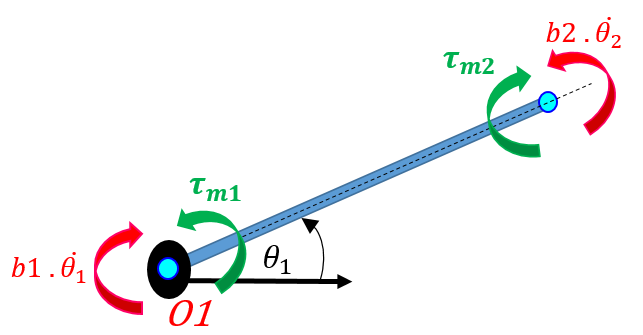

the_tau_mat_LINK_1 = ...
   [       0,                0,            0,                  0;          
           0,                0,            0,                  0;          
   (taum1_s),   (-b1_s*th1dot),   (-taum2_s),     (b2_s*th2dot)   ];

the_w_mat_LINK_1 = ...
   [       0,                0,            0,                  0;
           0,                0,            0,                  0;
      th1dot,           th1dot,       th1dot,             th1dot ];

And similarly for LINK 2:

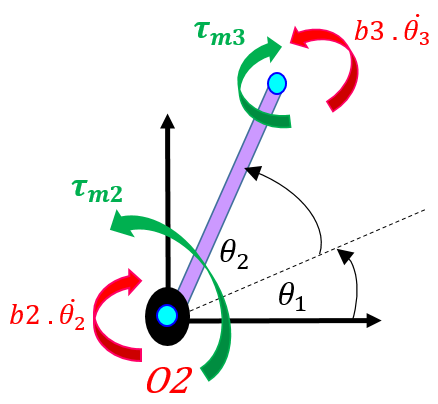

the_tau_mat_LINK_2 = ...
   [       0,                0,            0,                  0;          
           0,                0,            0,                  0;          
   (taum2_s),   (-b2_s*th2dot),   (-taum3_s),     (b3_s*th3dot)   ];

the_w_mat_LINK_2 = ...
   [       0,                0,            0,                  0;
           0,                0,            0,                  0;
   th_12_dot,        th_12_dot,    th_12_dot,          th_12_dot ];

And similarly for LINK 3:

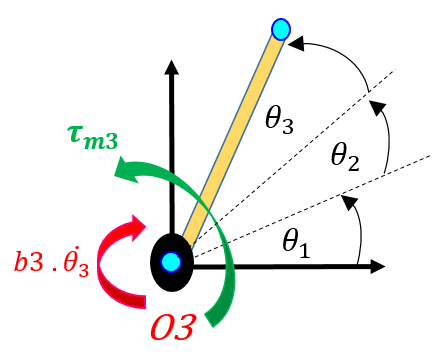

the_tau_mat_LINK_3 = ...
   [         0,                  0;          
             0,                  0;          
     (taum3_s),     (-b3_s*th3dot)   ];

the_w_mat_LINK_3 = ...
   [         0,                  0;
             0,                  0;
     th_123_dot,         th_123_dot ];

So concatenate these into single matrices:

the_tau_mat_actual = [the_tau_mat_LINK_1, the_tau_mat_LINK_2, the_tau_mat_LINK_3];
the_w_mat_actual   = [  the_w_mat_LINK_1,   the_w_mat_LINK_2,   the_w_mat_LINK_3];

Now let's compute $Q_k$:


$$Q_k = 
\sum_{i=1}^{Nf_{nc}}
\pmatrix{
\vec{F_i} \thinspace . \thinspace \frac{\partial \vec{v \thinspace _i}}{\partial \dot{q \thinspace}_k}
}  \enspace + \enspace
\sum_{j=1}^{N\tau_{nc}}
\pmatrix{
\vec {\tau_j} \thinspace . \thinspace \frac{\partial \vec{\omega \thinspace _j}}{\partial \dot{q \thinspace}_k}
}
$$


To do this we'll create a generalised force object using the class <`bh_genF4manips_CLS`>

genF_OBJ = bh_genF4manips_CLS( the_tau_mat_actual, ...
                               the_w_mat_actual, ...
                               actual_list_SYM_pos, ...
                               holder_list_SYM_pos);

And now calculate our system's generalised forces:                          

genF_OBJ = genF_OBJ.calc_genF();

What do the $Q_k's$ look like?

genF_OBJ.show_genF_holder()


#######################################################
### q = TH1_s
### 
### Qk (HOLDER) is: 
### 
      taum1_s - TH1_s_D*b1_s
#######################################################
### q = TH2_s
### 
### Qk (HOLDER) is: 
### 
      taum2_s - TH2_s_D*b2_s
#######################################################
### q = TH3_s
### 
### Qk (HOLDER) is: 
### 
      taum3_s - TH3_s_D*b3_s

And we can retrieve the individual $Q_k's$ as well :

the_Q1    = genF_OBJ.get_Qk(    1, 'holder')

$$the\_Q1 = {\mathrm{taum}}_{1,s}-{\mathrm{TH}}_{1,s,D}\,b_{1,s}$$

Or we can retrieve all of the $Q_k's$ :

the_Qk_vec = genF_OBJ.get_Qk('all', 'holder')

$$the\_Qk\_vec = \left(\begin{array}{c} {\mathrm{taum}}_{1,s}-{\mathrm{TH}}_{1,s,D}\,b_{1,s}\\ {\mathrm{taum}}_{2,s}-{\mathrm{TH}}_{2,s,D}\,b_{2,s}\\ {\mathrm{taum}}_{3,s}-{\mathrm{TH}}_{3,s,D}\,b_{3,s} \end{array}\right)$$

## Absorb the Generalised Forces:

We can insert these Generalised forces into the "Lagrangian" object that we created earlier:

lag_OBJ = lag_OBJ.calc_eom(genF_OBJ);

 Now echo our equations:

lag_OBJ.get_eom( 1:3, 'holder', 'RHS')

$$ans = \left(\begin{array}{c} {\mathrm{taum}}_{1,s}-{\mathrm{TH}}_{1,s,D}\,b_{1,s}\\ {\mathrm{taum}}_{2,s}-{\mathrm{TH}}_{2,s,D}\,b_{2,s}\\ {\mathrm{taum}}_{3,s}-{\mathrm{TH}}_{3,s,D}\,b_{3,s} \end{array}\right)$$

## Now let's get the M,C,K,G,Q matrices:

We can express our system equations of motion in the following form:


$$M(q).\ddot{q} \enspace + \enspace
C(q,\dot{q}).\dot{q} \enspace + \enspace
K(q).q \enspace + \enspace
 g(q) = Q$$


 lag_OBJ = lag_OBJ.create_MCKGQ();

Retrieve the MCKGQ struct:

res_T = lag_OBJ.get_MCKGQ()

res_T =   bh_MCKGQ_CLS with properties:

           M: [3×3 sym]
           C: [3×3 sym]
           K: [3×3 sym]
           G: [3×1 sym]
           Q: [3×1 sym]
     ACC_col: [3×1 sym]
     VEL_col: [3×1 sym]
     POS_col: [3×1 sym]
    acc_eoms: [3×1 sym]


And let's have a look at each of these terms:

Here's **M**:

res_T.M

$$ans = \begin{array}{l} \left(\begin{array}{ccc} {\mathrm{I1G}}_{s}+{\mathrm{I2G}}_{s}+{\mathrm{I3G}}_{s}+\frac{{{\mathrm{L1X}}_{s}}^{2}\,m_{1,s}}{4}+{{\mathrm{L1X}}_{s}}^{2}\,m_{2,s}+{{\mathrm{L1X}}_{s}}^{2}\,m_{3,s}+\sigma_{4}+{{\mathrm{L2X}}_{s}}^{2}\,m_{3,s}+\sigma_{5}+{\mathrm{L1X}}_{s}\,{\mathrm{L2X}}_{s}\,m_{2,s}\,\cos\left({\mathrm{TH}}_{2,s}\right)+2\,{\mathrm{L1X}}_{s}\,{\mathrm{L2X}}_{s}\,m_{3,s}\,\cos\left({\mathrm{TH}}_{2,s}\right)+\sigma_{6}+\sigma_{7} & \sigma_{2} & \sigma_{3}\\ \sigma_{2} & {\mathrm{I2G}}_{s}+{\mathrm{I3G}}_{s}+\sigma_{4}+{{\mathrm{L2X}}_{s}}^{2}\,m_{3,s}+\sigma_{5}+\sigma_{6} & \sigma_{1}\\ \sigma_{3} & \sigma_{1} & \frac{m_{3,s}\,{{\mathrm{L3X}}_{s}}^{2}}{4}+{\mathrm{I3G}}_{s} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{m_{3,s}\,{{\mathrm{L3X}}_{s}}^{2}}{4}+\frac{{\mathrm{L2X}}_{s}\,m_{3,s}\,\cos\left({\mathrm{TH}}_{3,s}\right)\,{\mathrm{L3X}}_{s}}{2}+{\mathrm{I3G}}_{s}\\ \sigma_{2}={\mathrm{I2G}}_{s}+{\mathrm{I3G}}_{s}+\sigma_{4}+{{\mathrm{L2X}}_{s}}^{2}\,m_{3,s}+\sigma_{5}+\frac{{\mathrm{L1X}}_{s}\,{\mathrm{L2X}}_{s}\,m_{2,s}\,\cos\left({\mathrm{TH}}_{2,s}\right)}{2}+{\mathrm{L1X}}_{s}\,{\mathrm{L2X}}_{s}\,m_{3,s}\,\cos\left({\mathrm{TH}}_{2,s}\right)+\sigma_{6}+\frac{\sigma_{7}}{2}\\ \sigma_{3}={\mathrm{I3G}}_{s}+\sigma_{5}+\frac{\sigma_{6}}{2}+\frac{\sigma_{7}}{2}\\ \sigma_{4}=\frac{{{\mathrm{L2X}}_{s}}^{2}\,m_{2,s}}{4}\\ \sigma_{5}=\frac{{{\mathrm{L3X}}_{s}}^{2}\,m_{3,s}}{4}\\ \sigma_{6}={\mathrm{L2X}}_{s}\,{\mathrm{L3X}}_{s}\,m_{3,s}\,\cos\left({\mathrm{TH}}_{3,s}\right)\\ \sigma_{7}={\mathrm{L1X}}_{s}\,{\mathrm{L3X}}_{s}\,m_{3,s}\,\cos\left({\mathrm{TH}}_{2,s}+{\mathrm{TH}}_{3,s}\right) \end{array}$$

Here's **C**:

res_T.C

Here's **K**:

res_T.K

$$ans = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

Here's **G**:

res_T.G

$$ans = \begin{array}{l} \left(\begin{array}{c} \frac{g_{s}\,\left({\mathrm{L2X}}_{s}\,m_{2,s}\,\cos\left({\mathrm{TH}}_{1,s}+{\mathrm{TH}}_{2,s}\right)+2\,{\mathrm{L2X}}_{s}\,m_{3,s}\,\cos\left({\mathrm{TH}}_{1,s}+{\mathrm{TH}}_{2,s}\right)+{\mathrm{L1X}}_{s}\,m_{1,s}\,\cos\left({\mathrm{TH}}_{1,s}\right)+2\,{\mathrm{L1X}}_{s}\,m_{2,s}\,\cos\left({\mathrm{TH}}_{1,s}\right)+2\,{\mathrm{L1X}}_{s}\,m_{3,s}\,\cos\left({\mathrm{TH}}_{1,s}\right)+{\mathrm{L3X}}_{s}\,m_{3,s}\,\sigma_{2}\right)}{2}\\ \sigma_{1}+\frac{{\mathrm{L2X}}_{s}\,g_{s}\,m_{2,s}\,\cos\left({\mathrm{TH}}_{1,s}+{\mathrm{TH}}_{2,s}\right)}{2}+{\mathrm{L2X}}_{s}\,g_{s}\,m_{3,s}\,\cos\left({\mathrm{TH}}_{1,s}+{\mathrm{TH}}_{2,s}\right)\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\mathrm{L3X}}_{s}\,g_{s}\,m_{3,s}\,\sigma_{2}}{2}\\ \sigma_{2}=\cos\left({\mathrm{TH}}_{1,s}+{\mathrm{TH}}_{2,s}+{\mathrm{TH}}_{3,s}\right) \end{array}$$

Here's **Q**:

res_T.Q

$$ans = \left(\begin{array}{c} {\mathrm{taum}}_{1,s}-{\mathrm{TH}}_{1,s,D}\,b_{1,s}\\ {\mathrm{taum}}_{2,s}-{\mathrm{TH}}_{2,s,D}\,b_{2,s}\\ {\mathrm{taum}}_{3,s}-{\mathrm{TH}}_{3,s,D}\,b_{3,s} \end{array}\right)$$

## Now create the MATLAB function blocks for Simulink:

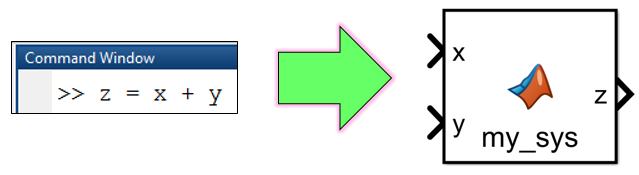

To use/solve these derived equations of motion we'll create a MATLAB Function block that can be used inside Simulink:

lag_OBJ.create_MLF_blocks()

## Implement and solve these equations of motion:

Although we could use MATLAB to numerically solve our system of ODEs, an alternate approach would be to use Simulink.  The Simulink models called:

-  <`bh_TRI_LAGR_compound_pendulum.slx`> 

implements our equations of motion.  Here are a few comments on this model:

- before running the Simulink model, run the script called <`bh_parameters_for_TRIPLE_compound_pendulum.mlx`> to load parameters (eg: inertias, initial conditions, etc) into the MATLAB workspace.

- In addition to implementing our hand derived equations of motion, we have also created a Simscape Multibody of the same 3 link manipulator.  We compare the results of our hand derivation to the Simscape model.